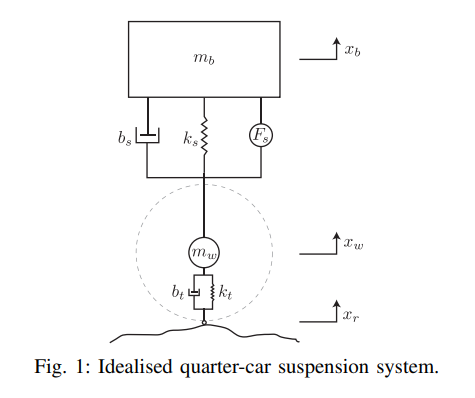

We use the above quater car mode with the following parameters


$$m_b =\;\textrm{kg};k_b =\;\frac{N}{m};$$

$$b_s =\;\frac{\textrm{Ns}}{s}$$



$$m_w =\;\textrm{kg};k_t =\frac{N}{m};b_t =\frac{\textrm{Ns}}{m}$$


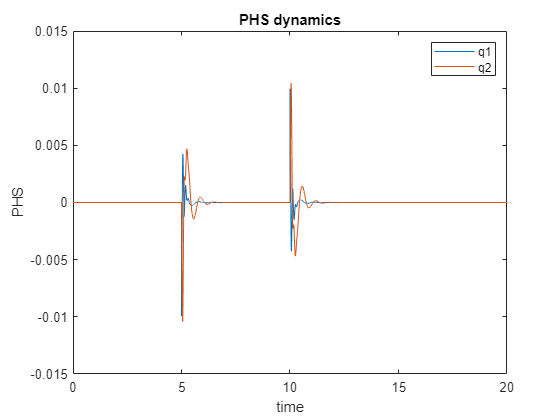

clc
clear
close all

tfinal = 20; dt = 0.001; % simulation parameters


mb=2.45; ks=950; bs=5;
%bs=0;
mw=1; kt=2500; bt=5;
M = [mw+mb mb;mb mb]; K=[kt 0;0 ks];
G1 = [bt;0]; G2 = [-1;0]; 
D = diag([bt,bs]); G = [0;1];
A_hat = [-D -eye(2);eye(2) zeros(2)];
B_hat = [G;zeros(2,1)];

%desired control parameters
a1 = 3.45; a2=2.45; a3=2.45;
Md = [a1 a2;a2 a3];
b2=21;
Dd = [bt*a1/(mw+mb) 0;0 b2];
kz=294;
Kd = [kt*(mw+mb)/a1 0;0 kz];
Ja = [0 -1;1 0];

lambda = 1; % convergence rate for control law

xr = 0; xr0 = xr;
x0 = [0;0;0;0]; x = x0; t = 0; H_sys = 0; 
p10 = mb*x(2); p1 = p10; p20 = mw*x(4); p2 = p20; p=[p1;p2];
q10 = x(1); q1 = q10; q20 = x(3); q2 = q20; q=[q1;q2];
xw = q10 + xr0; xb = q20 + xw;
p_hat = p - G1*xr0; q_hat = q - G2*xr0;
phs0 = [p_hat;q_hat]; phs = phs0;
h_hat=0; pe_hat=0; ke_hat=0; % initial conditions

PHS = []; T = []; 
Q = [];P = [];
Xb = []; Xw = []; Xr = []; 
H_hat=[]; PE_hat=[]; KE_hat=[];% initialize memory

while (t <= tfinal)
    T = [T,t]; PHS = [PHS,phs];
    H_hat=[H_hat,h_hat]; PE_hat=[PE_hat,pe_hat]; KE_hat=[KE_hat,ke_hat];
    Q = [Q,q]; P = [P,p]; 
    Xb = [Xb,xb]; Xw = [Xw,xw]; Xr = [Xr,xr];

    if(t>10)
        xr = 0;        
    elseif (t>5) && (t<10)
        xr = 0.01;
    else
        xr = 0;
    end

    KK = [p_hat(1)+bt*xr; p_hat(2)];
    ke_hat = 0.5*KK'*inv(M)*KK;
    pe_hat = 0.5*kt*(q_hat(1)-xr)^2 + 0.5*ks*q_hat(2)^2;
    h_hat = ke_hat + pe_hat; %total energy
    
    %desired energy
    phi = 0.5*kz*q(2)^2; %desired potential energy shaping
    pe_des = 0.5*kt*q(1)^2*(mw+mb)/a1 + phi;
    H_des = 0.5*p'*inv(Md)*p + pe_des;
    
    %control law
    u = pinv(G)*(D*(inv(M)*p) + (Ja-Dd)*inv(Md)*p + K*q - Md*inv(M)*([kt*q(1)*((mw+mb)/a1);kz*q(2)]))*lambda;
    %u = lambda*(h_hat)/2;
    %u=0;
    phs = phs + dt*(A_hat*([inv(M)*[phs(1)+bt*xr;phs(2)];(kt*(phs(3)-xr));phs(4)*ks]) + B_hat*u'); %diff eqn
    p_hat = phs(1:2);
    q_hat = phs(3:4);

    %recover original coordinates
    q = q_hat+G2*xr; 
    p = p_hat+G1*xr;
    xw = q(1) + xr;
    xb = q(2) + xw;

    t = t + dt; % time increment
end

figure(1)
plot(T,Q);
ylabel('PHS')
xlabel('time')
legend('q1','q2')
title('PHS dynamics')

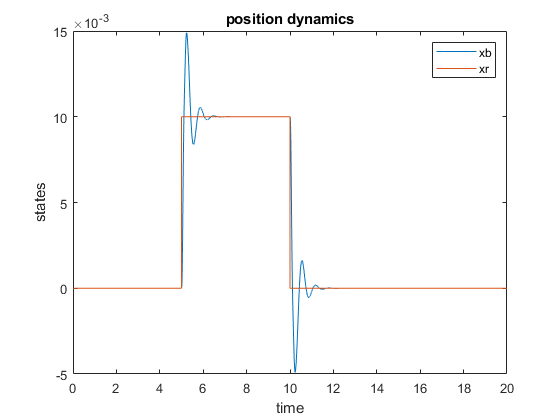

figure(2)
plot(T,Xb); hold on;
%plot(T,Xw); hold on;
plot(T,Xr);
ylabel('states')
xlabel('time')
legend('xb','xr')
title('position dynamics')
hold off

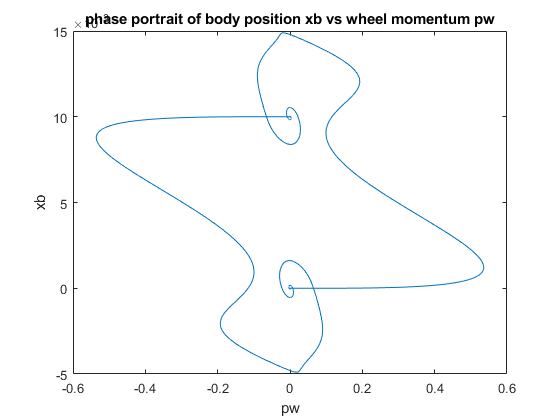

figure(3)
plot(P(1,:),Xb); hold on;
ylabel('xb')
xlabel('pw')
title('phase portrait of body position xb vs wheel momentum pw')
hold off

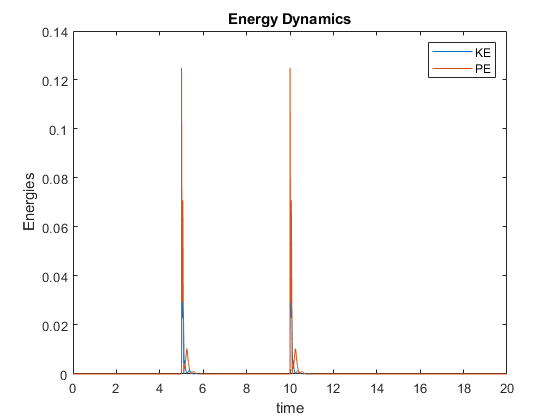

figure(4)
%plot(T,H_hat); hold on;
plot(T,KE_hat); hold on;
plot(T,PE_hat);
ylabel('Energies')
xlabel('time')
legend('KE','PE')
title('Energy Dynamics')
hold off